# Assignment 2

# Comparison of the exponential and running mean for random walk model

Ahmed Baza

Ahmed Elgohary

Mohamed Sayed

Ziad Baraka

## Part 1: Determination of optimal smoothing constant in exponential

1- conducting a simulation experiment. First generating a true trajectory, then generating measurements of this true trajectory.

clc; clear all; close all;

N1 = 3000; 
N2 = 300; 
X1 = zeros(N1,1);
X2 = zeros(N2,1);
X1(1) = 10;
X2(1) = 10;
for i = 2:N1 
    X1(i) = X1(i-1) + normrnd(0,sqrt(13))    ;    
end
for i = 2:N2
    X2(i) = X2(i-1) + normrnd(0,sqrt(13))   ;      
end

1.2.Generate measurements z of the process X

Z1 = zeros(N1,1);
Z2 = zeros(N2,1);
for i = 1:N1 
    Z1(i) = X1(i) + normrnd(0,sqrt(8))  ;      
end
for i = 1:N2
    Z2(i) = X2(i) + normrnd(0,sqrt(8)) ;    
end

2. Identify ${\sigma^2 }_W$ and  ${\sigma^2 }_{\eta }$ using the identification method 

v1 = zeros(N1,1);
v2 = zeros(N2,1);
rho1 = zeros(N1,1);
rho2 = zeros(N2,1);
for i = 3:N1
    v1(i) = Z1(i-1) -  Z1(i-2);
    rho1(i) = Z1(i) - Z1(i-2); 
end
for i = 3:N2
    v2(i) = Z2(i-1) -  Z2(i-2);
    rho2(i) = Z2(i) - Z2(i-2); 
end
Ev1 = (1/(N1-1)) * sum(v1.^2);
Erho1 = (1/(N1-1)) * sum(rho1.^2);
Ev2 = (1/(N2-1)) * sum(v2.^2);
Erho2 = (1/(N2-2)) * sum(rho2.^2);

sw1 = Erho1 - Ev1;
se1 = (Ev1 - sw1)/2;
sw2 = Erho2 - Ev2;
se2 = (Ev2 - sw2)/2;

3. Determine optimal smoothing coefficient in exponential smoothing

x1 = sw1 / se1;
alpha1 = (-x1 + sqrt(x1^2 +4*x1))/2;
x2 = sw2 / se2;
alpha2 = (-x2 + sqrt(x2^2 +4*x2))/2;


4. Perform exponential smoothing with the determined smoothing coefficient. Plot results. For the comparison add measurements, true values of process and exponentially smoothed data.

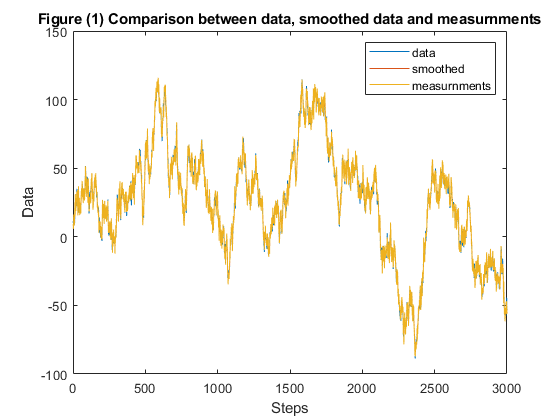

X1_smoothed = zeros(N1,1);
X2_smoothed = zeros(N2,1);

X1_smoothed(1) = Z1(1);
X2_smoothed(1) = Z2(1);

for i = 2:N1
X1_smoothed(i) = X1_smoothed(i-1) + alpha1 * (Z1(i) - X1_smoothed(i-1));
end
for i = 2:N2
X2_smoothed(i) = X2_smoothed(i-1) + alpha2 * (Z2(i) - X2_smoothed(i-1));
end

figure(1)
plot(1:N1,X1,1:N1,X1_smoothed,1:N1,Z1)
title('Figure (1) Comparison between data, smoothed data and measurnments')
xlabel('Steps')
ylabel('Data')
legend({'data','smoothed','measurnments'})

Figure (1) above shows how the exponentialy smoothed data is biased towards the measurnments more thatn the generated data. Mainly because alpha is higher than 0.5. That is not ver good actually, as we see it is greatly affected by the errors in the measurnments and became very noisy as well.

## Part 2: Comparison of methodical errors of exponential and running mean.�

1. Generation of a true trajectory using the random walk model

sw3 = 28^2;
se3 = 97^2;

X3 = zeros(N2,1);
X3(1) = 10;
for i = 2:N2
    X3(i) = X3(i-1) + normrnd(0,sqrt(sw3))   ;      
end

2. Generation measurements of the process.

Z3 = zeros(N2,1);
for i = 1:N2
    Z3(i) = X3(i) + normrnd(0,sqrt(se3)) ;    
end

3. Determination of optimal smoothing coefficient 

x3 = sw3 / se3;
alpha3 = (-x3 + sqrt(x3^2 +4*x3))/2;

4. Determination of the window size M

M = (2-alpha3)/alpha3;

5. Perform exponential smoothing with the determined smoothing coefficient. Plot results. For the comparison add measurements, true values of process and exponentially smoothed data.

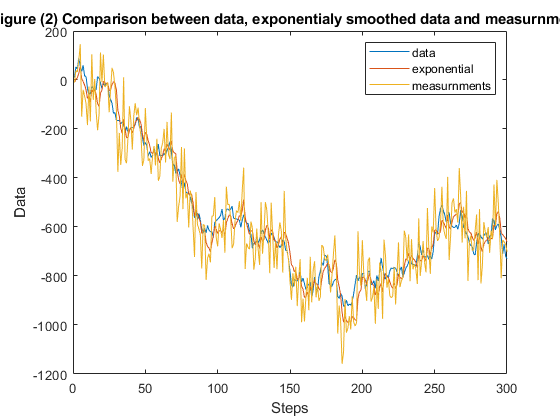

X3_exp= zeros(N2,1);
X3_exp(1) = Z3(1);

for i = 2:N2
X3_exp(i) = X3_exp(i-1) + alpha3 * (Z3(i) - X3_exp(i-1));
end

figure(2)
plot(1:N2,X3,1:N2,X3_exp,1:N2,Z3)
title('Figure (2) Comparison between data, exponentialy smoothed data and measurnments')
xlabel('Steps')
ylabel('Data')
legend({'data','exponential','measurnments'})

Figure (2) above compares between the generated data, exponentialy smoothed data and measurnments. The measurnments are so noisy. For that, choosing the alpha wit such small value shifts the smoothed data closer to the original data itself, reducing the weight of the noisy measurments. 

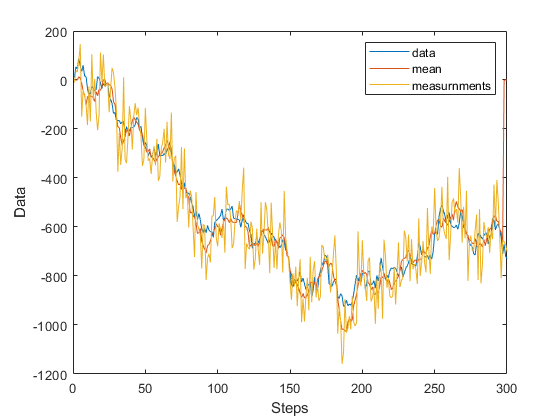

X3_mean= zeros(N2,1);
M = round((M-1)/2)*2+1;
m=(M-1)/2;
for i =  (m+1):N2-m
X3_mean(i) = 1/M * sum(Z3(i-m:i+m));
end
figure(3)
plot(1:N2,X3,1:N2,X3_mean,1:N2,Z3)
xlabel('Steps')
ylabel('Data')
legend({'data','mean','measurnments'})

Figure (3) above compares between the generated data, runing mean smoothed data and measurnments. The measurnments are so noisy. For that, choosing window size M equals 7 shifts the smoothed data closer to the original data itself, reducing the weight of the noisy measurments. 

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

For Assignment 3: Backward exponential smoothing

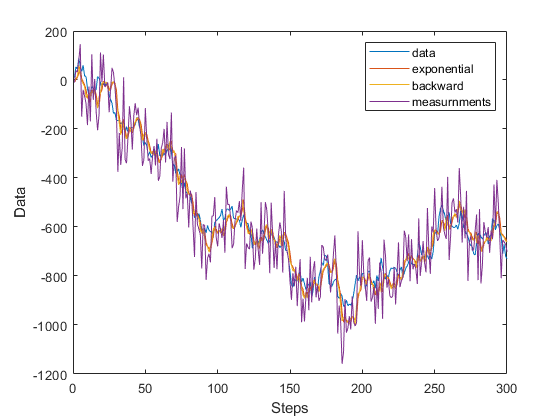

X3_back= zeros(N2,1);
X3_back(N2) = X3_exp(N2);

for i = N2-1:-1:1
X3_back(i) = X3_exp(i+1) + alpha3 * (X3_exp(i) - X3_back(i+1));
end

figure(3)
plot(1:N2,X3,1:N2,X3_exp,1:N2, X3_back,1:N2,Z3)
xlabel('Steps')
ylabel('Data')
legend({'data','exponential','backward','measurnments'})